

t = 0:0.01:500; 

% --- SZUKANIE WZMOCNIENIA KRYTYCZNEGO ---
% Dla wahadła K_kryt musi być > m*g*l (moment grawitacji).
% m*g*l = 1 * 9.81 * 0.15 = 1.47.
% Spróbujmy wartości w tych okolicach.
% Zmieniaj tę wartość ręcznie, aż uzyskasz stałą amplitudę na wykresie!

K_critical = -0.47; % Przykładowa wartość (Dostosuj ją!)
% Jeśli wykres rośnie -> Zmniejsz K
% Jeśli wykres gaśnie -> Zwiększ K (lub odwrotnie, zależnie od tłumienia)

% Zamknięcie pętli (Feedback ujemny)
G_closed = feedback(G_s * K_critical, 1);

% Wymuszenie - małe wychylenie (np. impuls siły lub warunek początkowy)
% Użyjmy impulse zamiast step, bo step wymusza stały błąd uchybu
[y, t_out] = impulse(G_closed, t);

%% 3. ANALIZA WYKRESU (Obliczanie Tu)
% Znajdowanie szczytów oscylacji
[pks, locs] = findpeaks(y, t_out);

% Sprawdzenie czy mamy oscylacje
if length(locs) > 1
    T_u = mean(diff(locs)); % Średni okres oscylacji (Ultimate Period)
    fprintf('Znaleziono oscylacje!\n');
    fprintf('Wzmocnienie krytyczne Ku = %.4f\n', K_critical);
    fprintf('Okres krytyczny       Tu = %.4f s\n', T_u);
    
    % --- 4. OBLICZENIE NASTAW PID (Klasyczny Ziegler-Nichols) ---
    % Wzory dla regulatora PID:
    Kp = 0.6 * K_critical;
    Ti = 0.5 * T_u;
    Td = 0.125 * T_u;
    
    Ki = Kp / Ti;
    Kd = Kp * Td;
        
    fprintf('\n=== ZALECANE NASTAWY PID ===\n');
    fprintf('Kp = %.4f\n', Kp);
    fprintf('Ki = %.4f\n', Ki);
    fprintf('Kd = %.4f\n', Kd);
    fprintf('============================\n');
else
    fprintf('Brak wystarczającej liczby oscylacji. Zmień K_critical.\n');
end

Znaleziono oscylacje!


Wzmocnienie krytyczne Ku = -0.4700


Okres krytyczny       Tu = 11.7229 s



=== ZALECANE NASTAWY PID ===


Kp = -0.2820


Ki = -0.0481


Kd = -0.4132


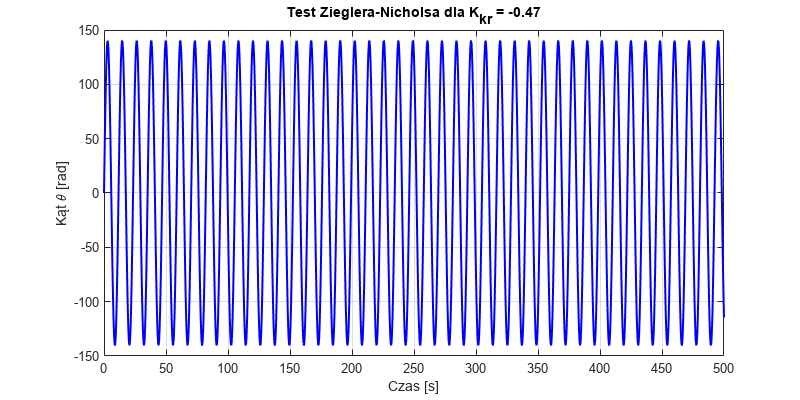


%% 5. RYSOWANIE
figure('Position', [100, 100, 800, 400]);
plot(t_out, y, 'b', 'LineWidth', 1.5);
title(['Test Zieglera-Nicholsa dla K_{kr} = ' num2str(K_critical)]);
xlabel('Czas [s]');
ylabel('Kąt \theta [rad]');
grid on;

% Zapis wykresu
print('odp_skok_zigler.png', '-dpng', '-r400');